# Microarray Data Analysis

In this homework, you are going to analyze microarray data from the following study: [http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307](http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307) The study contains gene expression profiles of 677 samples from 125 distinct tissue types with 12 different disease states (including normal state).

The main task is to segregate the gene expression profiles based on distinct tissue types  and disease states.

Perform the analysis tasks described below and submit this mlx file (and any other auxiliary matlab files you write for this assignment), the mlx file of this file, and the following files:

diseasegene.txt

commongenes.txt

**Objectives:**

- Understand the gene expression using microarray 

- Differential gene expression

- Familiar with the GEO repository hosted at NCBI [http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)

- Understand the GEO structure,  GSE and GPL

- Download GEO data

- Understand the new  data type (DataMatrix), which is designed specifically for gene expression

- Map container function: containers.Map()

- Logical indexing

- Clustering and PCA analysis

- Volcano plot 

GSE7307, GPL570

%Download the data and parse it, change the d (gse.data) rownames to gene names from gpl
gse=bmes_downloadandparsegse7('GSE7307');
d = gse.Data;
I=genevarfilter(d, 'Percentile',99); % genevarfilter calculates the gene expression varaiaon.
d = d( I, :); % reatains the genes with higher varaion. 

% d: 547x677 datamatrix with Header information
headerInfo = gse.Header.Samples.characteristics_ch1;
% Diagnostic information for all data
info = gse.Header.Samples.characteristics_ch1(1,:);
% Platform ID from gse
gse.Header.Series.platform_id;

% Download the GPL data
gpl = bmes_downloadandparsegpl('GPL570');
%Information we get from each probe:
columnNames = gpl.ColumnNames;


# Translate probesets to gene symbols  ( the goal is to replace the d.rownames with the gene symbol from gpl)

  !platform_table_begin (probe id links gpl and gse data)



%Get the probe names and gene names from the gpl data set.
gplProbes = gpl.Data(:, strcmp(gpl.ColumnNames, 'ID'));

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

gplGenes  = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Symbol'));
% Get the gene names from the gse data set. These should be the same as the
% gpl gene names from the gpl data set. Going to map between these to get
% identifiers that work with both. In the gse, each row is a gene. Each
% column is a tissue sample. In the gpl data, each row is a sample and the
% ID column has the probe names and the gene symbol name has the gene
% names.
gseProbes = d.rownames;
% Mapping. Create a matrix that will be used for mapping.
myMap = zeros(numel(gseProbes),1);
% Create a map based on the size of gplprobes.
map = containers.Map(?);
for i=1:numel(gseProbes);
    if ?
    end
end
% Make a copy in case some names were not matched. Gsegenes is a variable
% that contains all the probe names.Gsegenes is for indexing.
gseGenes = gseProbes;
% Gsegenes is now a matrix that has a list of gene names in an order.
gseGenes(?) = gplGenes(?);
% Replace data matrix so uses genes as row names
d = d.rownames(':',gseGenes);

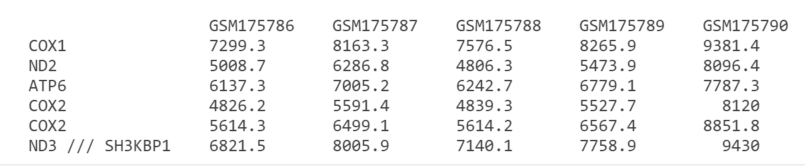

# Clustering Samples (tissue type and disease state)

Use k means clustering method to group all gene expressions in 4 clusters (independent from tissue type and disease state). investigate for each cluster, do the samples from normal and disease  have similar overall expression profiles (for all 12 disease states)? in this case, we are not segregating the tissue types.

% Get the tissue and disease types that we're analyzing.
tissue = gse.Header.Samples.characteristics_ch1(1,:);
tissueType = unique(tissue) % total 125 tissue types
disease = gse.Header.Samples.characteristics_ch1(4,:);
diseaseType = unique(disease) % total 12 disease, diseaseType(7) is normal
% Use kmeans to group the genes in 4 clusters 
    clust = kmeans(d,4,'dist','corr');
    
% for each diseaseType, compare two groups IdiseaseSamp and Inormal

for i = 1:numel(diseaseType) % 12 different disease types
    IdiseaseSamp = ?; % 1x677 logical array for patients with that diseaseType. 
   
    Inormal = ?; %  1x677 logical array for patients who are normal. This should be the same through the loop.
    group1 = IdiseaseSamp; 
    group2 = Inormal;
   
% for coding purpose, create a numerical vector to assign each sample to a group 1-2.
    Igroups = zeros(1,numel(disease));
    Igroups(group1) = ?;
    Igroups(group2) = ?;

%distribute this data in averages to plots for each disease    
    davg = zeros(4,4);
    subplot(3,4,i)
    for i = 1:4 % within clusters
        for j= 1:2 % within groups
            davg(i,j) = mean(d(?, ?)); % gene clusters in rows and patients (disease or normal) in columns
            % find the mean of all patients belong to the cluster ==i and group ==j.
            % 
        end
    end
    % Graphs the output in bar charts
    bar(davg)
    % title('Avg Exp Values for Clusters');
    xlabel('Cluster Number');
    ylabel('Gene Expression');
end

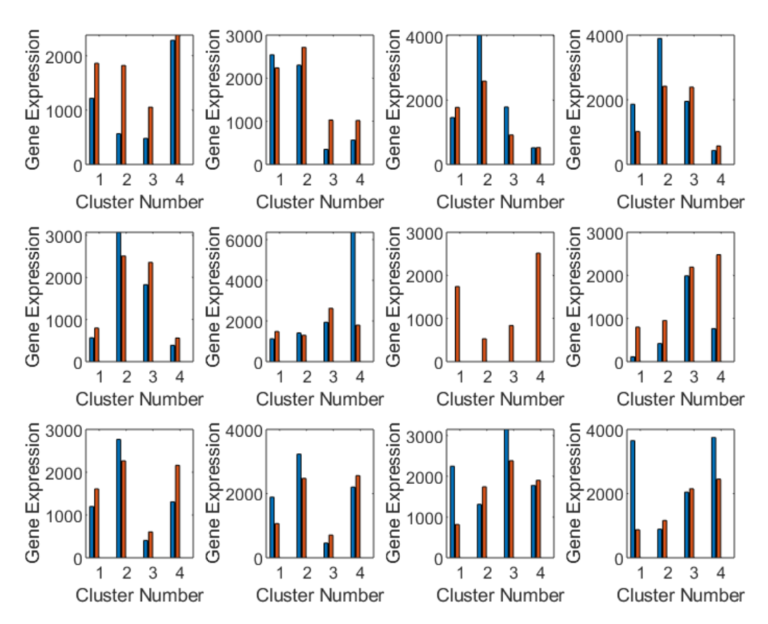

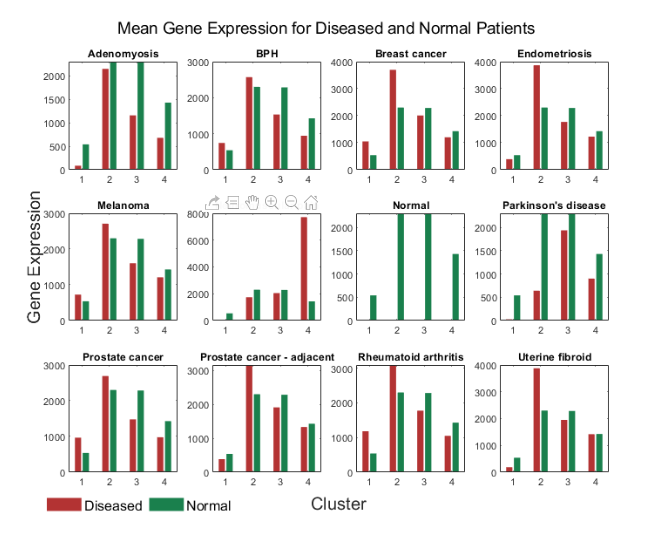

## Figure captions:

## Conclusions:

Use k means clustering-method to group all gene expressions in 4 clusters. Investigate for tissue type 1 of each disease type. Within each cluster, do the samples from normal and disease state have similar overall expression profiles (for all 12 disease states)? 

% compare tissue types for normal vs diseased (only first tissue type)

% Identify groups that you want to cluster in terms of diseases and tissue
% corelations
for i = 1:numel(diseaseType)
    IdiseaseSamp = ?; % patients with the diseasetype(i)
    diseaseTissue = unique(tissue(IdiseaseSamp)); % now, we need to segregate the tissue types, particularly the first tissue type 
    ItissueSamp = ? % define the logical array for  the first tissue type diseaseTissue (1) of disseasetype(i)
   
    
    ggroup1 = IdiseaseSamp ? ItissueSamp % define logical index array for patients with first tissue type of diseasetype (i) 
 
    ggroup2 = Inormal ? ItissueSamp % define logical index array for noraml patients with first tissue type of diseasetype (i) 
   
    
    IIgroups = zeros(1,numel(disease));
    IIgroups(ggroup1) = 1;
    IIgroups(ggroup2) = 2;
   
% User clust to cluser the data  
    clust = kmeans(d,4,'dist','corr');
%distribute this data in averages to plots for each disease    
    davg = zeros(4,4);
    subplot(3,4,i)
    for i = 1:4
        for j= 1:2
            davg(i,j) = ? %
        end
    end
    %Graphs the output in bar charts
    bar(davg)
    % title('Avg Exp Values for Clusters');
    xlabel('Cluster Number');
    ylabel('Gene Expression');
end

# Differential Gene Expression in Disease

What are the genes that are differentially expressed in each disease? For each disease, compare the disease samples with the normal samples of the same tissue. Save the results into an Excel worksheet named diseasegene, with the header row containing "disease", "gene", "pvalue", "negfoldchange". Only show significant genes. Get disease type.

In this dataset, the gene expression number is not at a log scale.

disease = gse.Header.Samples.characteristics_ch1(4,:);
diseaseType = unique(disease);
%Find a unique list of all the disease states

diseasestates = [diseaseType(1:6) diseaseType(8:12)];
% diseasestates = [diseaseType(1)];
% Find a unique list of all the tissues
sampletissue = gse.Header.Samples.characteristics_ch1(1,:);
tissuetypes = unique(sampletissue);
exceldata = [];
% placeholder


- The main goal is to segregate the patients based on both diseasetype and  the tissuetype. 

- 677 patients (677 columns) and each patient has a defined disease type and a tissue type. gse.Header.Samples.characteristics_ch1(4,:) and tissue type gse.Header.Samples.characteristics_ch1(1,:)

- Unique 12 disease types (1-12) and redefine 11 disease states #1-6 and # 8-12 of the disease types plus #7 as normal 

- Unique 125 tissue types

- For each patient (total 677), who should have a disease state (total 12), associated tissue types (total125).

- **Go through each disease state and its associated unique tissue types to compare the gene expression of normal tissue and disease tissue.**

- For example, disease state 1 "adenomyosis" has only one unique tissue type "myometrim", you will compare the gene expression between normal myometrim and disease myometrium.  Disease state 2 may have several unique tissue types.

- Loop through disease states and unique tissue types associated with the disease states to find the significant genes. 

- Everything is based on a logical index (1X677). 

- Inormal (1x677): indicates patients are normal; 

- Idisease: patients have a certain disease, 

- Itissuetype: patients have a certain tissue type

- **Idisease_tissue: patient with a certain disease and a certain tissue type. **

- **Ibase: normal patients with a certain tissue type; **

- write/record every significant gene in a text file. 

diseasestates = [diseaseType(1:6) diseaseType(8:12)]
for i = ? % loop through diseasestates
    
    
    Idisease = ? % Grab the logical indices for the specific disease diseasestates(i)
    
    corrtissuetypes = sampletissue (?) % 1x677 logical array. These are the tissue types that have that disease  
    
    uniquetissuetype = ? % For example, disease state 1 "adenomyosis" has only one unique tissue type "myometrim",
   
    
    Inormal = strcmp(?) %Find the indices of the normal samples.
   
    % This is the index for the tissue type we are looking for uniquetissuetype(1) of diseasestates(i)
    % Itissuetype = strcmp(sampletissue,uniquetissuetype(1));
    
    Itissuetype = zeros(1,size(sampletissue,2));
    
    
    for j = ? % loop through the unique tissue types (uniquetissuetype) for disease i 
        Itissuetype= strcmp(sampletissue,uniquetissuetype(j));
        Ibase = Inormal ? Itissuetype  % 1x677 array, normal samples with a certain tissue type
        Idisease_tissue= Idisease ? Itissuetype % 1x677 array, patients with a certain disease and a certain tissue type
    if sum(Idisease_tissue) < 1 | sum(Ibase) < 1
        'There is only one data set, so there is no significance'
    else
        % calculate the p value comparing normal  and disease with the same tissue type
        [dpvals]=mattest(d (:, ibase) d (:, idisease_tissue) 'permute',1000); 
        
     % find the mean intensity (gene expression) to calculate the fold change
        negfcDisease = mean(?);  % find the mean intensity (gene expression) of  each gene for Ibase
        negfcNormal= mean(?);    % find the mean intensity (gene expression) of  each gene for Idisease_tissue
        negfc = zeros(size(negfcDisease,1), 1);
        
        for p=1:numel(negfcDisease) % assign the fold change
            negfc(p)=negfcDisease(p)/negfcNormal(p); % negfcNormal(p) is the same through the loop
        end
     
     % write the negfc to dpvals with ColNames as negfc. Check the primer. 
        dpvals=[?];
    
     % Find the significantly differently expressed genes in this disease
        I=find(dpvals(:,1)<=0.01);
        
     %Initialize the data for population
        nsig=numel(I);
        xlsdata1 = cell(nsig, 4);
        Sdisease= diseasestates{i};  % put diseasestates in Sdisease.
        
      % Get the data for each significant gene for disease state
        for k=1:nsig
            gene=dpvals.rownames{I(k)}; % put dpvals.rownames in gene
            if isempty(gene)
                gene = 'empty';
            end
            p=dpvals.double(I(k), 1); % put dpval (:,1) in p
            nfc=dpvals.double(I(k), 2); % put dpval (:,2) in nfc
            xlsdata1(k,:) = {Sdisease gene p nfc}; % now xlsdata1 (nsig, 4) has all the data
            
        end
        
        % Append the data matrix
        exceldata = [exceldata; xlsdata1]; 
        
    end
    end
    
    
    
end

% grab the data for the excel file exceldata(:,i)
diseasename = ?;
genesymbol = ?;
pvalue = ?;
fc = ?;
% for macs, you can use xlswrite for a combination of text and numbers. I
% used a text writing code and manually changed it to an excel file instead.


% write it to diseasegene.txt
T = ?
writetable(T,'diseasegene.txt');

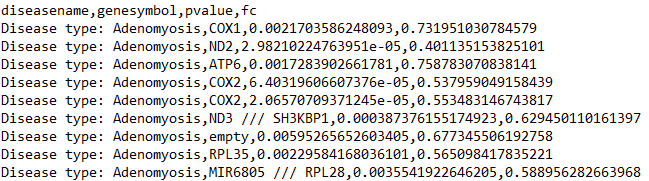

# Commonly Altered Genes in Diseases

Now, based on the above results, we will ask the question: Are there any genes commonly differentially expressed for different diseases? For each of the differentially expressed genes you found, report the number of diseases they are involved in. Save the results into an Excel worksheet named commongenes, with the header row containing "gene", "numdiseases", "diseaselist" (CSV of diseases that the go term is found in).

%Find a unique list of genes
significantgenes = unique(genesymbol);
%Initialize data matrices

% Run through the significant genes and grab the number of diseases they
% were involved in by indexing for the gene and summing the number of
% "ones" where it is true. Then get the list of genes by combining the
% disease names into one cell.
for i=1:numel(significantgenes)


end
% Get the data from here and make it able to write into a table.


%write in a text file because mac's cant use xlswrite
T2 = ?;

writetable(T2,'commongenes.txt');

## 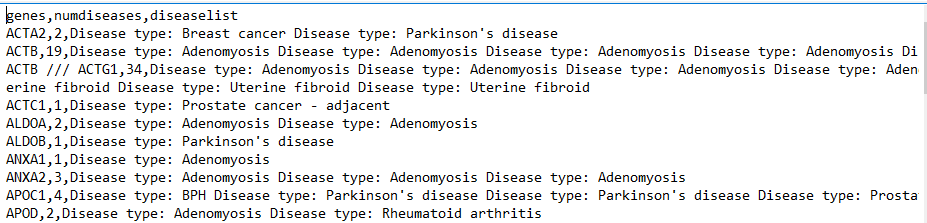

## Bonus:  Housekeeping Genes

Housekeeping genes are those that are required for the maintenance of basic cellular function and are typically constitutively expressed. Using only the normal tissue samples, can you find these housekeeping genes? You need to make your own assumptions and analysis. Explain how you decided to define and find the housekeeping genes. Save your results to an Excel worksheet named "housekeeping". In addition to the gene names, report "housekeepingness" of these genes, according to the criteria you came up with.

hint: most common in all normal tissues.